## Perturbatively shifting NE in Ising game

Consider the TFIM $H = -J\sum Z_jZ_{j+1} - g \sum X_j$, we know that the ground state is an NE. Now we shift the parent Hamiltonian (and hence the natural definition for local energies) by $\lambda \sum Z_j$. We have state $|\psi \rangle$as ground state of TFIM, and $|\psi \rangle + |\delta \psi \rangle$as the new NE for the shifted Hamiltonian.

format short
% create the set of linear equations
J = 1;
Gm = 1.2;
h = 0.1; % start with IM with transverse field only
N = 6;
bc = 'PBC';
[H,Hloc] = hIM(J,Gm,h,N,bc,1); % create global and local Hamiltonians

[spec,lam] = eig(H,'vector');
v = spec(:,1); % this is the ground state of the model

conds = zeros(3*N,2^N);
for j = 1:N
    for a = 1:3
        G = fG(j,a,Hloc);
        conds((j-1)*3+a,:) = v'*G;
    end
end
 


% convert to real entries
for j = 1:3*N
    conds(j,:) = conds(j,:)/(conds(j,1)/norm(conds(j,1)));
end
ker = null(conds);

% verify that the shifted state is indeed a Nash equilibrium

dl = 0.1;
[Hp,Hploc] = hIM(J,Gm,dl,N,bc,1);

[spec0,lam0] = eig(Hp,'vector');
% To construct a new state which is Nash but not a ground state,
% can shift the original ground state by dl
v0 = spec0(:,1);
v1 = v+ dl*ker(:,3);
v1 = v1/norm(v1);
d0 = 0; d1 = 0; dref = 0;
for j = 1:N
    for a = 1:3
        % d0 is the exact ground state of this model
        d0 = d0 + abs(v0'*fG(j,a,Hploc)*v0);
        % d1 is the perturbative prediction
        d1 = d1 + abs(v1'*fG(j,a,Hploc)*v1);
        % reference state, using the ground state of XIM
        dref = dref + abs(v'*fG(j,a,Hploc)*v);
    end
end


### Iterative algorithm for finding perturbed NE

% use the same parameters as in the previous section
F = @(phi) fF(phi,N,v,Hloc);
dF = @(phi) fdF(phi,N,v,Hloc);
max(max(fdG(N,1,1)))

ans = 0.0000 + 2.0000i

### Iterative algorithm for finding NE

% choose initial state as the ground state
e1 = 1e-5;
dv = (1-2*rand(2^N,1)); % the perturbation
dv = spec(:,2);
dv = dv./norm(dv);
v = sqrt(1-e1)*spec(:,1)+sqrt(e1)*dv;

% v = 1-2*rand(2^N,1);
% v = v/norm(v);
% v = zeros(2^N,1);
% v(1) = 1;
% compute the projection of v on Ker(conds)
m = ker*(ker'*v);


eps = 1; iter = 1; l = 1;

Gs = zeros(2^N,2^N,3*N);
for j = 1:N
    for a = 1:3
        Gs(:,:,(j-1)*3+a) = fG(j,a,Hloc);
    end
end

itermax = 500;
vset = zeros(2^N,itermax); % show the convergence of vectors explicitly
vset(:,1) = v;
eset = zeros(1,itermax);
lset = zeros(1,itermax);


while and(or(eps>1e-4,l<1e-3),iter<itermax+1)
    
    % record v at ith iteration
    vset(:,iter) = real(v);
    
    % find eps and l for current iteration
    conds = zeros(3*N,2^N);
    for j = 1:N
        for a = 1:3
            conds((j-1)*3+a,:) = v'*Gs(:,:,(j-1)*3+a);
        end
    end
    ker = null(conds);
    eps = abs(1-abs(dot(v,ker*(ker'*v))));
    eset(iter) = eps;
    
    l = 0;
    for j = 1:N
        for a = 1:3
            l = l + abs(v'*Gs(:,:,(j-1)*3+a)*v);
        end
    end
    lset(iter) = l;
    
    % update v
    v = ker*(ker'*v);
    v = v/norm(v);
    
    iter = iter + 1;
    disp(['iter = ',num2str(iter),'; eps = ',num2str(eps),'; l = ',num2str(l)])
end

iter = 2; eps = 6.8001e-07; l = 0.0032799


## Iteration scheme 2

F0 = @(phi) fF0(phi,N,Hloc);
dF0 = @(phi) fdF0(phi,N,Hloc);
df0 = @(phi,h) fdf(phi,N,Hloc,h);
f0 = @(phi) ff(phi,N,Hloc);

e1 = 1e-2;
dv = (1-2*rand(2^N,1)); % the random perturbation
% dv = spec(:,2);
dv = dv./norm(dv);
phi = sqrt(1-e1)*spec(:,1)+sqrt(e1)*dv; % the perturbed state
phi_init = phi;

**Gradient descent:** This is because the map $F‘$ has non-trivial kernel. This means minimizing $\| F(\phi) - F'(\phi) \mathbf{v}\|$ essentially leads to 0 (solution always exist for an underdetermined linear system). While we are looking for self-consistent soutions. 

% make iterations
% convergence condition:
iter = 1;

% converge if the function converges to the 
ftol = 1e-14;

% terminate if beyond maximal allowed iterations
max_iter = 50;

% initial conditions
% phi
phi = 1-2*rand(2^N,1);
phi = phi/norm(phi);
% fval
fval = f0(phi);
% aopt
aopt = 0.033;

% record data
fvals = [];
aopts = [];
tic
while and(fval>ftol,iter<max_iter)
    
    % for computations
    h = sqrt(2.2e-16); % the finite difference used for finding derivatives
    tol = min(1e-4,1e-3*aopt);
    options = optimset('TolX',tol);
    
    
    if iter == 1
        disp(['iter = 1, fval = ',num2str(fval),', aopt = ',num2str(aopt)])
    end
    % choose the descent direction to be the gradient
    nn = -df0(phi,h)/norm(df0(phi,h));
    
    % choose the amount of descent, i.e. stepsize e
    % by exact line search
    % Construct a function handle
    ftemp = @(ak) f0(phi+ak*nn);
    
    % use builtin opt package to minimize ftemp
    [aopt,fval] = fminbnd(ftemp,0,2*aopt,options);
    
    phi = phi + aopt*nn;
    phi = phi/norm(phi); % normalize the resultant state
    iter = iter + 1;
    
    disp(['iter = ',num2str(iter),', fval = ',num2str(fval),', aopt = ',num2str(aopt)]);

    fvals = [fvals,fval];
    aopts = [aopts,aopt];
end

iter = 1, fval = 1.0391, aopt = 0.033


iter = 2, fval = 0.40202, aopt = 0.065982
iter = 3, fval = 0.014488, aopt = 0.10286
iter = 4, fval = 0.0026725, aopt = 0.01571
iter = 5, fval = 0.00062492, aopt = 0.0057703
iter = 6, fval = 0.00017009, aopt = 0.0028895
iter = 7, fval = 4.7408e-05, aopt = 0.0013804
iter = 8, fval = 1.3339e-05, aopt = 0.00078597
iter = 9, fval = 3.7563e-06, aopt = 0.0003854
iter = 10, fval = 1.0581e-06, aopt = 0.00022117
iter = 11, fval = 2.9805e-07, aopt = 0.00010854
iter = 12, fval = 8.3956e-08, aopt = 6.2302e-05
iter = 13, fval = 2.3649e-08, aopt = 3.0574e-05
iter = 14, fval = 6.6617e-09, aopt = 1.755e-05
iter = 15, fval = 1.8765e-09, aopt = 8.6124e-06
iter = 16, fval = 5.2859e-10, aopt = 4.9436e-06
iter = 17, fval = 1.489e-10, aopt = 2.426e-06
iter = 18, fval = 4.1942e-11, aopt = 1.3925e-06
iter = 19, fval = 1.1815e-11, aopt = 6.8337e-07
iter = 20, fval = 3.328e-12, aopt = 3.9226e-07
iter = 21, fval = 9.3745e-13, aopt = 1.925e-07
iter = 22, fval = 2.6407e-13, aopt = 1.1049e-07
iter = 23, fval = 7.438

toc

Elapsed time is 27.443437 seconds.


## Analyzing the convergence of states

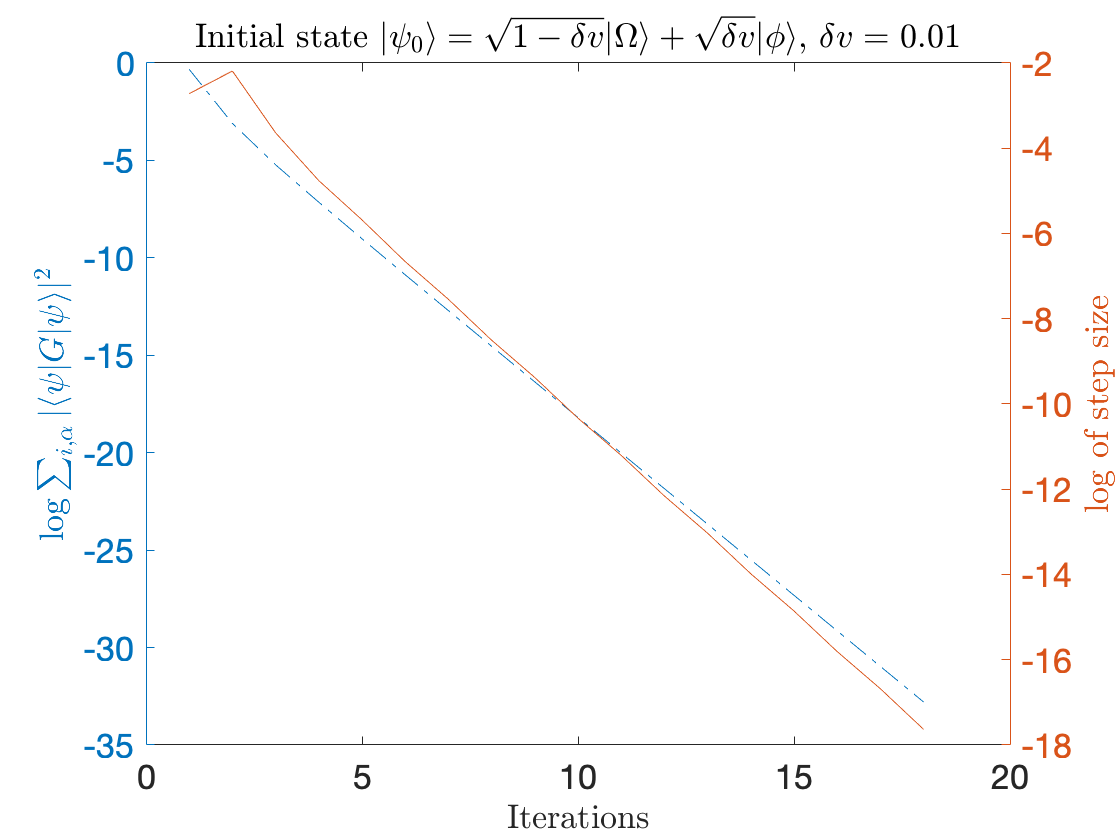


figure();
yyaxis left
% check that the convergence is reached
% plot(1:itermax,eset,'*-','LineWidth',1.5)
% ylabel('Convergence measure $\epsilon$')

plot(1:iter-1,log(fvals),'-.')
ylabel('$\log \sum_{i,\alpha} | \langle \psi | G | \psi \rangle |^2 $')
yyaxis right
% % make sure the convergent state satisfy the kernel condition
% plot(1:itermax,lset,'o-.','LineWidth',0.5)
% ylabel('Kernel measure $l = \sum_{G} |\langle \psi |G| \psi \rangle |$')
% format short

plot(1:iter-1,log(aopts))
ylabel('log of step size')
xlabel('Iterations')
title(['Initial state $|\psi_0 \rangle = \sqrt{1-\delta v}|\Omega\rangle + \sqrt{\delta v}|\phi\rangle$, $\delta v =$ ',num2str(e1)])

## Determining the properties of the obtained convergent state

- Characterize the subspace spanned by these states

- start from the ground state, check whether ground state is an attractor, do the same for other eigenstates

*It seems that the random perturbation from the ground state ends up are attracted by the ground state. but the convergence in individual entries of the *$2^N$ *dimensional vector is insufficient.*

% create a perturbation around the ground state
e1 = 1e-2;
dv = (1-2*rand(2^N,1)); % the random perturbation
dv = dv./norm(dv);
phi0 = sqrt(1-e1)*spec(:,1)+sqrt(e1)*dv;

ftol = 1e-14;
[phi_1,fval] = NEsolver(phi0,f0,df0,ftol)

phi =     0.6782
    0.2118
    0.2112
    0.1298
    0.2134
    0.0693
    0.1054
    0.0672
    0.2058
    0.0731


fval = 2.4273e-14


% start from some random state
phi0 = 1-2*rand(2^N,1);
phi0 = phi0/norm(phi0);
[phi_1,fval] = NEsolver(phi0,f0,df0,ftol)

phi =     0.1022
    0.0457
   -0.1203
   -0.1274
    0.1303
    0.0035
    0.0274
    0.0218
   -0.0468
   -0.0490


fval = 9.4282e-15

function S = PauliI(N,i,a)

ans = 1.0327e-07


S = 1;
switch a
    case 1
        for j = 1:N
            if j ~= i
                S = kron(S,eye(2));
            else
                S = kron(S,[0,1;1,0]);
            end
        end
    case 2
        for j = 1:N
            if j ~= i
                S = kron(S,eye(2));
            else
                S = kron(S,1i * [0,-1;1,0]);
            end
        end
    case 3
        for j = 1:N
            if j ~= i
                S = kron(S,eye(2));
            else
                S = kron(S,[1,0;0,-1]);
            end
        end
        
end

end

function dG = fdG(N,i,a)
% to create i[sigma,Z], the perturbed longitudinal field
dG = 1i*(PauliI(N,i,a)*PauliI(N,i,3)-PauliI(N,i,3)*PauliI(N,i,a));
end

function y = fF(phi,N,v,Hloc)
y = zeros(3*N,1);
for j = 1:N
    for a = 1:3
        G = fG(j,a,Hloc);
        dG = fdG(N,j,a);
        y(3*(j-1)+a) = (v'*dG*v)*(phi'*G*phi)-4*real(v'*G*phi)*real(v'*dG*phi);        
    end
end

end

function A = fdF(phi,N,v,Hloc)
A = zeros(3*N,2^N);
for j = 1:N
    for a = 1:3
        G = fG(j,a,Hloc);
        dG = fdG(N,j,a);
        A(3*(j-1)+a,:) = 2*(v'*dG*v)*(phi'*G) - 2*real(v'*G*phi)*(v'*dG) - 2*real(v'*dG*phi)*(v'*G);
    end
end
end

function y = fF0(phi,N,Hloc)
% the norm
y = zeros(3*N,1);
for j = 1:N
    for a = 1:3
        G = fG(j,a,Hloc);
        y(3*(j-1)+a) = phi'*G*phi;
    end
end

% y = norm(y)/(phi'*phi);
% y = y^2;
end

function A = fdF0(phi,N,Hloc)
A = zeros(3*N,2^N);
for j = 1:N
    for a = 1:3
        G = fG(j,a,Hloc);
        A(3*(j-1)+a,:) = (phi'*G*phi)*(phi'*G);
    end
end
end

function J = fJ0(F,x)
m = length(F(x));
n = length(x);
J = zeros(m,n);
h = 1e-6;
for j = 1:n
    dx = zeros(n,1);
    dx(j) = h; % the increment in the jth direction    
    J(:,j) = (F(x+dx)-F(x))/h;    
end

end

function y = ff(phi,N,Hloc)
% the normalization-independent expectation values
y = sum(fF0(phi,N,Hloc).^2)/(phi'*phi)^2;
end

function dfdx = fdf(phi,N,Hloc,h)
% the derivative of the Rn to R map
dfdx = zeros(length(phi),1);
for i = 1:length(phi)
    dx = zeros(length(phi),1);
    dx(i) = h;
    dfdx(i) = (ff(phi+dx,N,Hloc) - ff(phi-dx,N,Hloc))/(2*h);
end
end

function [phi,fval] = NEsolver(phi0,f0,df0,ftol)
% input: phi0 - an initial guess
% f0 - the sum-of-square problem
% df0 - the gradient of sum-of-square problem, computed using finite
% difference of some input scale h.
% ftol: tolerence to treat function output as 0
phi = phi0/norm(phi0); % normalize incoming state

% fval
fval = f0(phi);

% aopt
aopt = 0.033;

% iter
iter = 1;
max_iter = 30;

h = sqrt(2.2e-16); % the finite difference used for finding derivatives

while and(fval>ftol,iter<max_iter)
    
    % for computations
    tol = min(1e-4,1e-3*aopt);
    options = optimset('TolX',tol);
    
    % choose the descent direction to be the gradient
    nn = -df0(phi,h)/norm(df0(phi,h));
    
    % choose the amount of descent, i.e. stepsize e
    % by exact line search
    % Construct a function handle
    ftemp = @(ak) f0(phi+ak*nn);
    
    % use builtin opt package to minimize ftemp
    [aopt,fval] = fminbnd(ftemp,0,2*aopt,options);
    
    phi = phi + aopt*nn;
    phi = phi/norm(phi); % normalize the resultant state
    iter = iter + 1;
    
    % disp(['iter = ',num2str(iter),', fval = ',num2str(fval),', aopt = ',num2str(aopt)]);
end
end